%----------------------------------------%
% test comsol solution 'decoupled'       %
% cont and mom eqns                      %
% dvz/dt + (1/mn)(Te+Ti)dn/dz = 0        %
% dn/dt + (n)dvz/dz = 0                  %
% rlbarnett c3149416 070318              %
%----------------------------------------%

%--
% spatial domain
xmin = 0;
xmax = 2;
xax = linspace(xmin,xmax,101);
nptsx = length(xax);
dx = (xmax - xmin)/(nptsx-1);

%--
% temporal domain
tmin = 0;
tmax = 1;
tax = linspace(tmin,tmax,11);
nptst = length(tax);
dt = (tmax - tmin)/(nptst-1);

dt = 0.1000

%--
% constants
e = 1.6022e-19;
m = 1.67e-27;

%--
% parameters
Te = 5.0;
Ti = Te;
cs = sqrt((Te + Ti)*e/m);


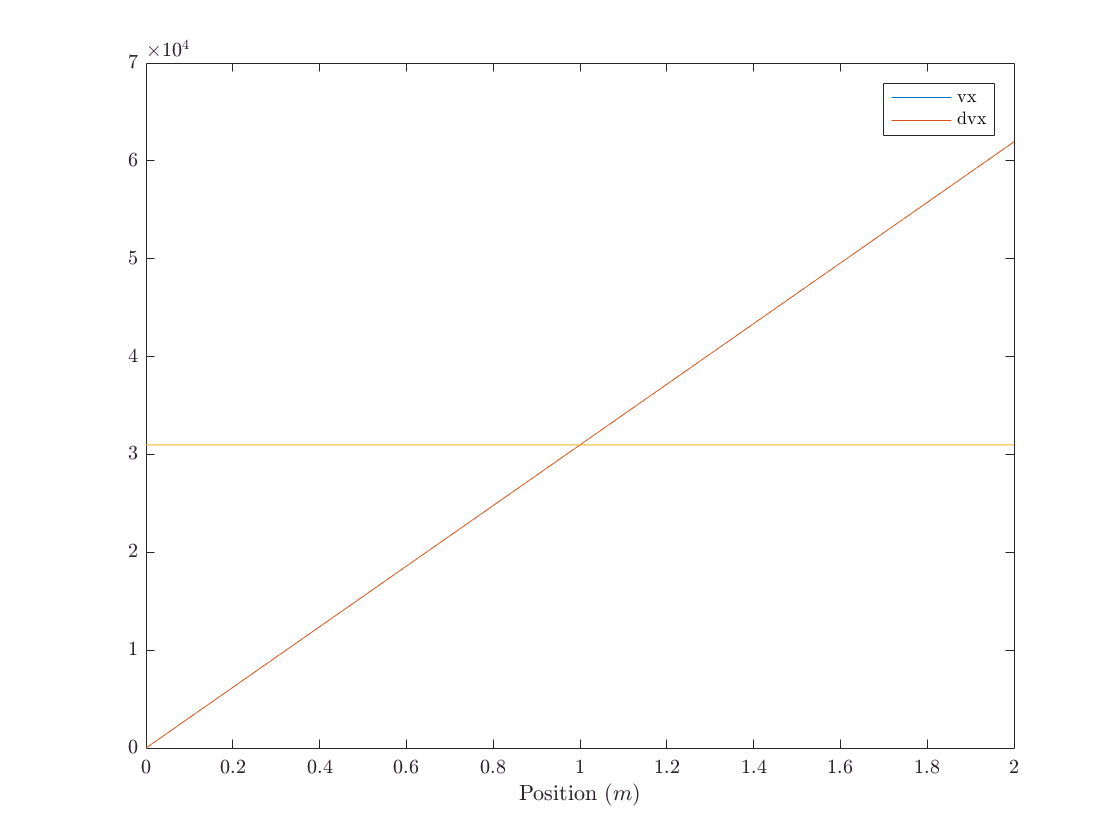

%--
% velocity
vx = cs*xax;
dvx = gradient(vx,x);

figure(1)
plot(xax,vx)
hold on
plot(xax,dvx)
legend('vx', 'dvx')
xlabel('Position ($m$)')
hold off